%chebyshev LPF
clc
clear all
close all
wp=input('enter pass band freq: ')

wp = 1000

ws=input('enter stop band freq: ')

ws = 2000

deltap=input('enter pass band ripple: ')

deltap = 3

deltas=input('enter stop band ripple: ')

deltas = 6

fs=10000

fs = 10000

omegap=(2/fs)*tan(wp/2)

omegap = 1.0585e-04

omegas=(2/fs)*tan(ws/2)

omegas = 2.9406e-04

den=log10(omegas/omegap)

den = 0.4438

del=1/deltap^2-1

del = -0.8889

delta=1/deltas^2-1

delta = -0.9722

num=2*log10(delta/del)

num = 0.0778

order=ceil(num/den)

order = 1

re=-20*log10(1/deltap)

re = 9.5424

fc=1000

fc = 1000

[b,a]=cheby1(order,re,fc/(fs/2),'low')

b =     0.1030    0.1030


a =     1.0000   -0.7939


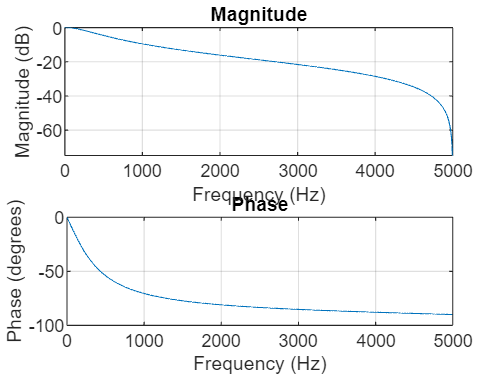

freqz(b,a,1000,fs)

%chebyshev HPF
clc
clear all
close all
wp=input('enter pass band freq: ')

wp = 1000

ws=input('enter stop band freq: ')

ws = 2000

deltap=input('enter pass band ripple: ')

deltap = 3

deltas=input('enter stop band ripple: ')

deltas = 7

fs=10000

fs = 10000

fc=1000

fc = 1000

omegap=2/fs*tan(wp/2)

omegap = 1.0585e-04

omegas=2/fs*tan(ws/2)

omegas = 2.9406e-04

delta=(1/deltas^2-1)

delta = -0.9796

del=1/deltap^2-1

del = -0.8889

num=2*log10(delta/del)

num = 0.0844

den=log10(omegas/omegap)

den = 0.4438

order=ceil(num/den)

order = 1

re=-20*log(1/deltap)

re = 21.9722

[b,a]=cheby1(order,re,fc/(fs/2),'high')

b =     0.1975   -0.1975


a =     1.0000    0.6051


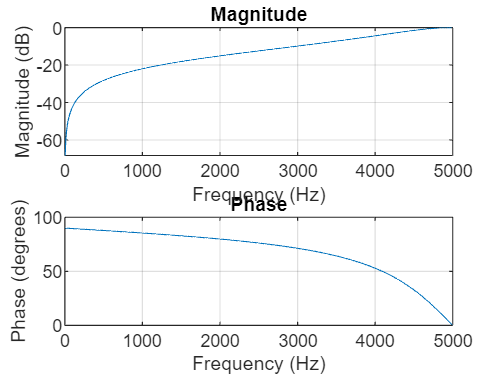

freqz(b,a,1000,fs)

% Chebyshev BPF
clc
clear all
close all

wp = input('Enter pass band freq: ');
ws = input('Enter stop band freq: ');
deltap = input('Enter pass band ripple: ');
deltas = input('Enter stop band ripple: ');
wp1 = input('Enter pass band freq-1: ');
ws1 = input('Enter stop band freq-1: ');
fs = 10000;
fc = 1000;

omegap = 2/fs * tan(wp/2);
omegas = 2/fs * tan(ws/2);
omegap1 = 2/fs * tan(wp1/2);
omegas1 = 2/fs * tan(ws1/2);
delta = 1/deltas^2 - 1;
del = 1/deltap^2 - 1;
num = 2 * log10(delta/del);
den = log10(omegas*omegas1/(omegap*omegap1));
re = -20 * log10(1/deltap);
order = ceil(num/den);
order=1

order = 1

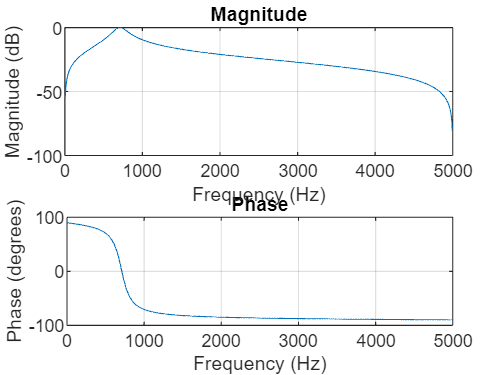

[b, a] = cheby1(order, re, [0.1, 0.2], 'bandpass');

freqz(b, a, 1000, fs);

%chebyshev BSF
clc
clear all
close all
wp=input('enter pass band freq: ')

wp = 1000

ws=input('enter stop band freq: ')

ws = 4000

deltap=input('enter pass band riple: ')

deltap = 3

deltas=input('enter stop band ripple: ')

deltas = 5

wp1=input('enter pass band freq-1: ')

wp1 = 5000

ws1=input('enter stop band freq-1: ')

ws1 = 7000

fs=10000

fs = 10000

fc=1000

fc = 1000

omegap=2/fs*tan(wp/2)

omegap = 1.0585e-04

omegas=2/fs*tan(ws/2)

omegas = -5.0620e-04

omegap1=2/fs*tan(wp1/2)

omegap1 = -1.7113e-04

omegas1=2/fs*tan(ws1/2)

omegas1 = 5.4445e-05

den=log10(omegas*omegas1/omegap*omegap1)

den = -7.3511

delta=1/deltas^2-1

delta = -0.9600

del=1/deltas^2-1

del = -0.9600

num=2*log10(delta/del)

num = 0

order=ceil(num/den)

order = 0

re=-20*log10(1/deltap)

re = 9.5424

order=1

order = 1

[b,a]=cheby1(order,re,[0.1,0.2],'stop')

b =     0.6906   -1.2460    0.6906


a =     1.0000   -1.2460    0.3812


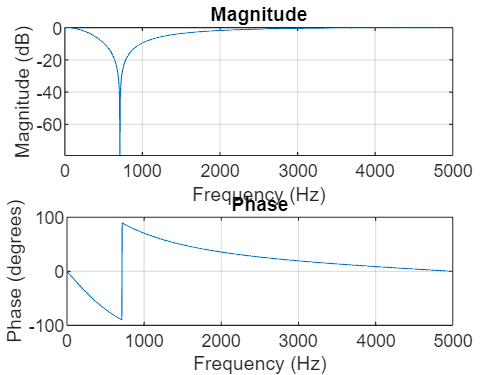

freqz(b,a,fc,fs)